Limpieza de pantalla

clear all
close all
clc


1 TIEMPO

tf= 6.3;             % Tiempo de simulación en segundos (s)
ts=0.005;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras
op = 11;

2 TRAYECTORIA DESEADA

%Ecuaciones paramétricas de la trayectoria deseada
if op == 1
    hxd = 2*cos(0.2*t); 
    hyd = 2*sin(0.4*t); 
elseif op == 2
    hxd = t - 3*sin(t);
    hyd = 4 - 3*cos(t); 
elseif op == 3
    hxd = 3*cos(t) - cos(3*t);
    hyd = 4*sin(3*t);
elseif op == 4
    hxd = cos(t) + (1/2)*cos(7*t) + (1/3)*sin(17*t); 
    hyd = sin(t) + (1/2)*sin(7*t) + (1/3)*cos(17*t); 
elseif op == 5
    hxd = 17*cos(t) + 7*cos(17 + 7*t); 
    hyd = 17*sin(t) - 7*sin(17 + 7*t);
elseif op == 6
     hxd = 2*cos(t); 
     hyd = 2*sin(t); 
elseif op == 7
    hxd = 5*t - 4*sin(t); 
    hyd = 5*t - 4*cos(t); 
elseif op == 8
    hxd = 4*cos(t) + cos(4*t);
    hyd = 4*sin(t) - sin(4*t);
elseif op == 9
    % Hexágono de radio 1
    num_lados = 6;
    r = 1;
    ang = linspace(0, 2*pi, num_lados+1);  % Vértices del hexágono

    % Coordenadas de los vértices
    x_hex = r * cos(ang);
    y_hex = r * sin(ang);

    % Interpolamos para generar N puntos a lo largo de la trayectoria
    puntos = length(x_hex);
    hxd = interp1(1:puntos, x_hex, linspace(1, puntos, N), 'linear');
    hyd = interp1(1:puntos, y_hex, linspace(1, puntos, N), 'linear');
 elseif op == 10
     hxd= 50*cos(8*t).*cos(t);
     hyd= 50*cos(8*t).*sin(t);
 elseif op == 11
    s = linspace(0, 2*pi, N); % Parametrización en el mismo número de muestras

    % Componentes de las trayectorias deseadas
    hxd = 12*sin(s) - 4*sin(3*s);
    hyd = 13*cos(s) - 5*cos(2*s) - 2*cos(3*s)-4*cos(16);

    % Velocidades deseadas (derivadas numéricas aproximadas)
    hxdp = [diff(hxd) 0]/ts; % La última derivada se añade como 0
    hydp = [diff(hyd) 0]/ts;
end


%Velocidades de la trayectoria deseada
hxdp=gradient(hxd, ts);
hydp=gradient(hyd, ts);

2. CONDICIONES INICIALES

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=hxd(1)  %Posición inicial eje x

x1 = 0

y1(1)=hyd(1)  %Posición inicial eje y

y1 = 9.8306

phi(1)=deg2rad(90); %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

4 CONTROL BUCLE DE SIMULACION

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[40 0;...
       0 40];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


5 APLICACIÓN DE CONTROL AL ROBOT

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

**SIMULACION VIRTUAL 3D**

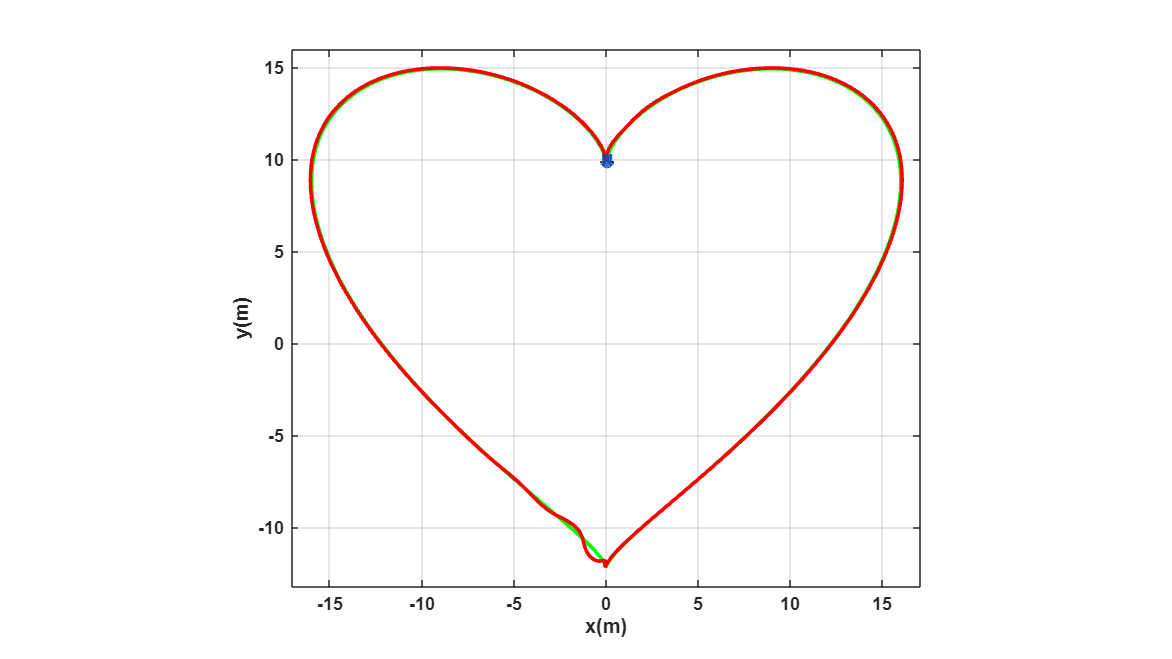

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

% Calcular rangos automáticamente basados en la trayectoria real
minX = min(x1) - 1;
maxX = max(x1) + 1;
minY = min(y1) - 1;
maxY = max(y1) + 1;

view(2); % Vista 3D
axis([minX maxX minY maxY 0 1]); % Rango ajustado a la trayectoria real

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

**Graficas**

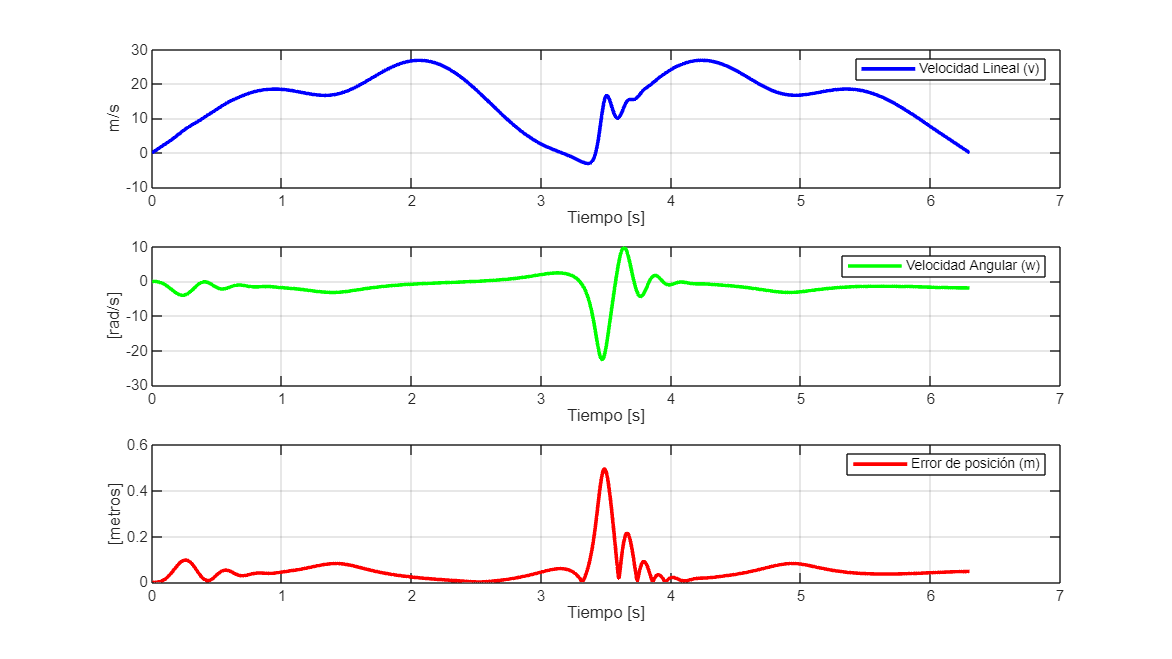

graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');